 %{
ES115 Engineering Computer Applications
Module 4 Project: Water Tank Fill-and-Drain

Author: Zulaikha Khan  
Instructor: Lynroy Grant  
Date: March 28, 2026  

Purpose:
This project models how the volume of water in a tank changes over time
during a filling and draining process. A piecewise function is used to
represent two different phases: filling and draining. The goal is to
visualize how the volume changes, determine specific times when the
volume reaches a certain value, and organize the data in a table.

Inputs (Knowns):
- Time values (t) from 0 to 25 minutes
- Filling model (0 ≤ t ≤ 10): V(t) = 5t + 20
- Draining model (t > 10): V(t) = -3(t - 10) + 70

Outputs (Unknowns):
- Volume of water at each time value
- Graph of volume vs time
- Time(s) when the volume equals 50 liters
- Table of time and corresponding volume values

Engineering Workflow and Algorithms:
- Define time values over the given interval
- Initialize volume array
- Apply piecewise conditions for filling and draining phases
- Plot volume vs time
- Use MATLAB functions to find when volume equals a specific value
- Create and display a table of results

MATLAB Tools / Functions Used:
- plot() for graphing
- logical indexing for piecewise conditions
- find() to locate specific volume values
- table() to organize data
- disp() for displaying results

Reflection After Completing the Project:
- I learned how to implement piecewise functions in MATLAB using logical
  indexing and how to model real-world situations like filling and draining.
- I also got better at interpreting graphs and extracting specific values
  from data.
- If I were to improve this project, I would make the model more realistic
  by using continuous transitions instead of exact breakpoints.
- Difficulty Rating: 4/10 — this project was mostly straightforward, but
  setting up the piecewise conditions correctly was important.
 %}



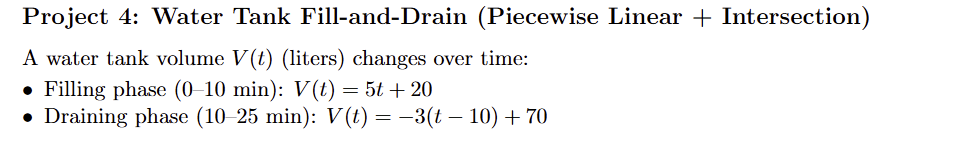

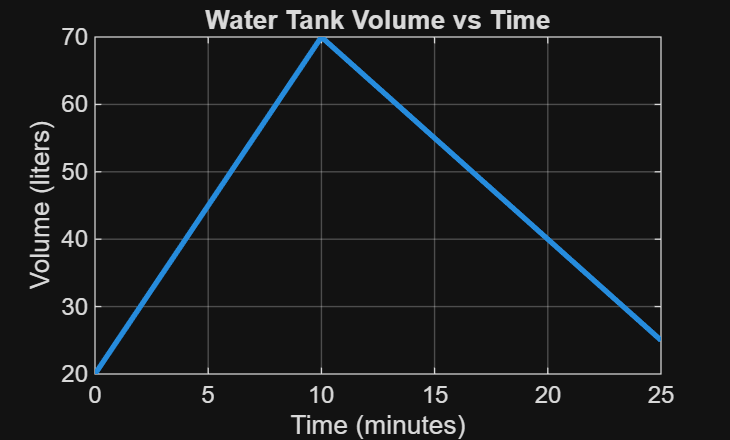

 
clear; clc; close all; 
 
% ---------------------------- 
% Define time values 
t = 0:1:25; 
 
% Initialize volume array 
V = zeros(size(t)); 
 
% ---------------------------- 
% Piecewise model 
 
% Filling phase (0–10 min) 
V(t <= 10) = 5*t(t <= 10) + 20; 
 
% Draining phase (10–25 min) 
V(t > 10) = -3*(t(t > 10) - 10) + 70; 
 
% ---------------------------- 
% Plot volume vs time 
figure; 
plot(t, V, 'LineWidth', 2); 
 
title('Water Tank Volume vs Time'); 
xlabel('Time (minutes)'); 
ylabel('Volume (liters)'); 
grid on; 

 
% ---------------------------- 
% Find when V = 50 liters 
index_50 = find(V == 50); 
 
t_50 = t(index_50); 
 
disp('Time(s) when volume is 50 liters:'); 

Time(s) when volume is 50 liters:


disp(t_50); 

     6



 
% ---------------------------- 
% Create table (at least 12 rows) 
T = table(t', V', 'VariableNames', {'Time_min', 'Volume_L'}); 
disp('Sample table (first 12 rows):'); 

Sample table (first 12 rows):


disp(T(1:12,:)); 

    Time_min    Volume_L
    ________    ________

        0          20   
        1          25   
        2          30   
        3          35   
        4          40   
        5          45   
        6          50   
        7          55   
        8          60   
        9          65   
       10          70   
       11          67   

